`2. 对以下各周期序列进行频谱分析`

`选FFT的变换区间`N`为`8`和`16`两种情况分别对以上序列进行频谱分析。分别打印其幅频特性曲线，并进行对比、分析、讨论。`

这里很显然, x4(n) 的周期是 8, x(5)n的周期是16

% ===========定义x4(n),x5(n)==============
N1 = 8;
N2 = 16;
n1 = 0:N1-1;
n2 = 0:N2-1;
x4n1 = cos(pi/4*n1);
x4n2 = cos(pi/4*n2);
x5n1 = cos(pi/4*n1) + cos(pi/8*n1);
x5n2 = cos(pi/4*n2) + cos(pi/8*n2);



x4(n), 可以看到因为采样点数大于等于周期, 所以不会发生频谱混叠现象

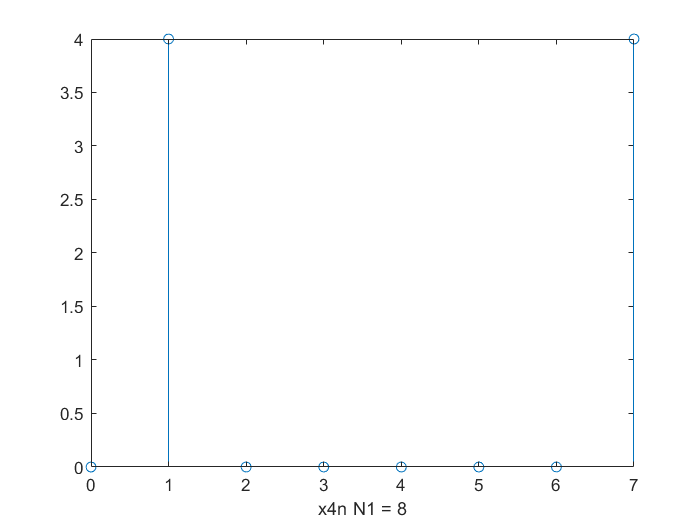


%================x4(n)================
y4n1 =  fft(x4n1, N1) ; % x1n N1 = 8
stem(0:length(y4n1) - 1, abs(y4n1))
xlabel("x4n N1 = 8");

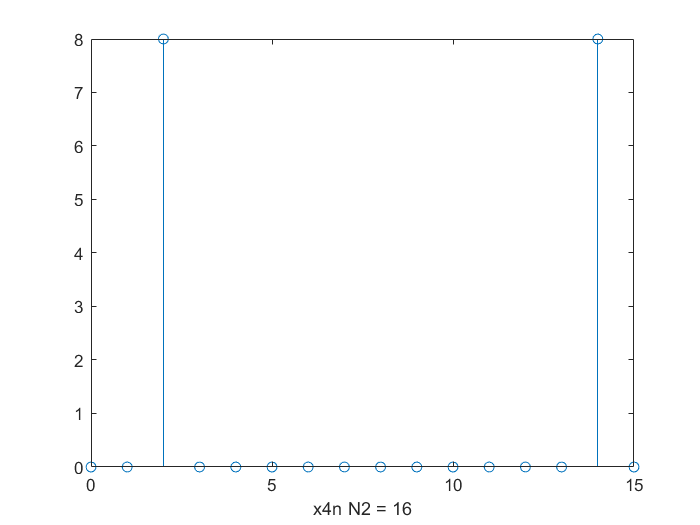


y4n2 =  fft(x4n2, N2) ; % x1n N1 = 8
stem(0:length(y4n2) - 1, abs(y4n2))
xlabel("x4n N2 = 16");

x5(n),可以看到N1因为采样点数小于等于周期, 所以发生了频谱混叠现象

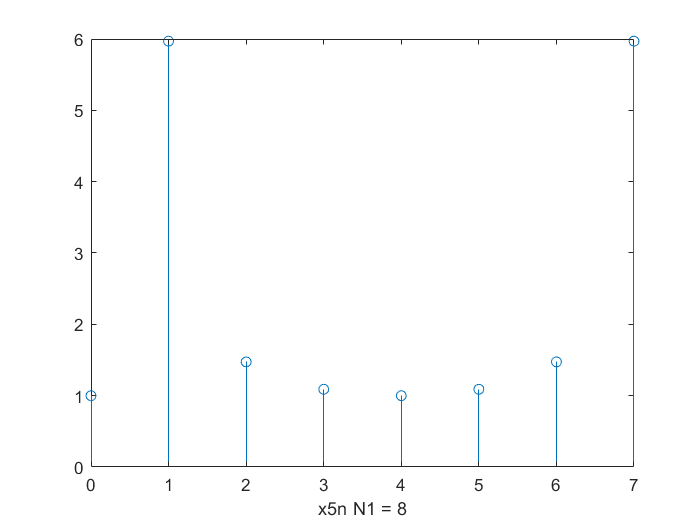

%================x5(n)================
y5n1 =  fft(x5n1, N1) ; % x1n N1 = 8
stem(0:length(y5n1) - 1, abs(y5n1))
xlabel("x5n N1 = 8");

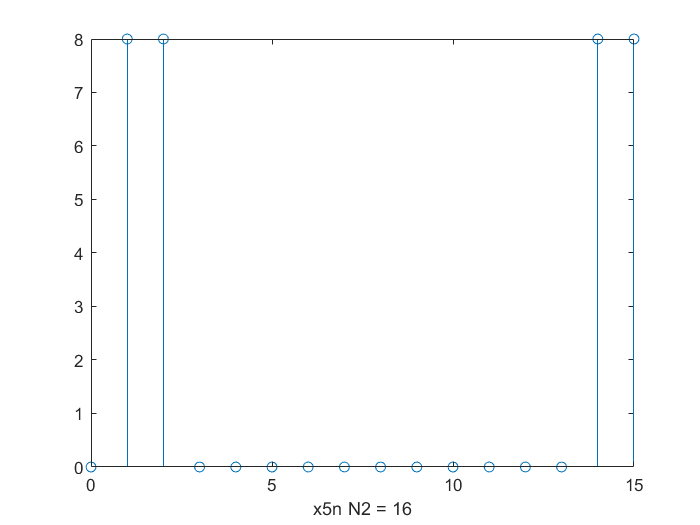


y5n2 =  fft(x5n2, N2) ; % x1n N1 = 8
stem(0:length(y5n2) - 1, abs(y5n2))
xlabel("x5n N2 = 16");